## Stat exam prep & general help

- notes

# Week 1

clc; clear;

% data = xlsread("Data_M4STI1_2017E.xlsx", 'K:L');
data = readtable("Data_M4STI1_2017E.xlsx")


opg3_brembo = rmmissing(table2array(data(:,"Opg3_Brembo")));
opg3_cl = rmmissing(table2array(data(:, "Opg3_CI")));

deskripts(opg3_brembo',"Brembo")
deskripts(opg3_cl',"Brembo")


## Visuals

rng(2)
randmat = [2.2:0.1:3.5, 3.6, 4.2:0.1:5.2];

stemleafplot(randmat, -1)

figure
histogram(randmat, 2:1:6);

title("Histo")


### Histo med categorical

figure

cat = categorical(floor(randmat), [2, 3, 4, 5], ["Starts with 2","Starts with 3","Starts with 4","Starts with 5"]);

histogram(cat)
ylim([0,10])


## Boxplots

figure("Visible","on")
boxplot([randmat',randmat'])

% Brembo og Cl
figure("Visible","on")
boxplot([opg3_cl, opg3_brembo],["Cl","Brembo"],"Notch","on")
hold on
yline(h(1))
yline(h(2))
hold off


% normrnd data
n1 = normrnd(5,1,100,1);
n2 = normrnd(6,1,100,1);

[d,g,h,j]=ztest(n1, 5,1,"Alpha",0.05);

figure
boxplot([n1,n2], ["Jeff","John"],"Notch","on")

hold on
yline(h(1))
yline(h(2))
hold off




# Week 2

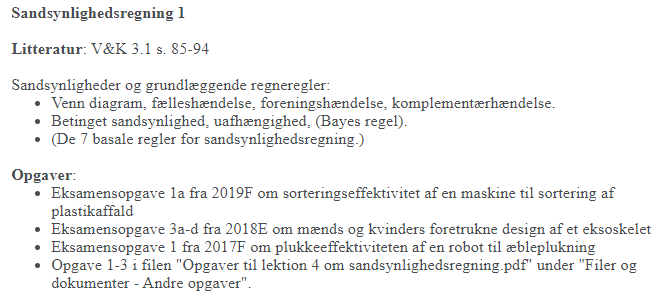

## Sorteringseffektivitet

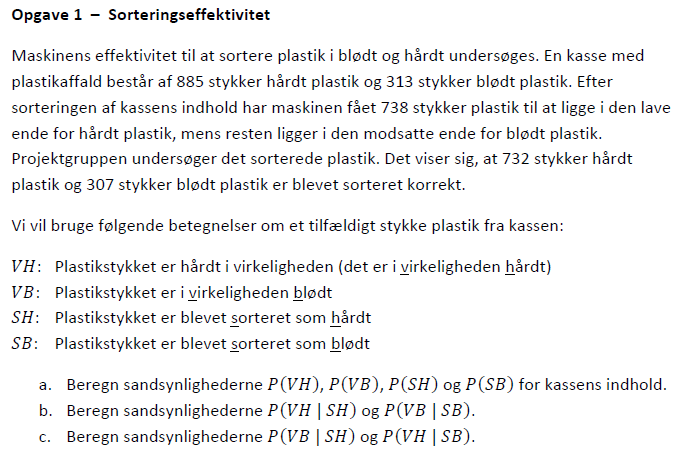

clc; clear;

% Faktiske data
n_hard = 885; % Antal hårde plast stykker
n_soft = 313; % Antal bløde plast stykker
n_tot = n_hard + n_soft; % Total population af plast

% Maskinens sortering
m_hard = 738;              % Maskinen har sorteret så mange hårde
m_soft = n_tot - m_hard;   % Maskinen har sorteret så mange bløde

% Antal der er sorteret korrekt
k_hard = 732;
k_soft = 307;

%---------------- Udregninger ----------------%

% Sandsynligheder til a)
pVH = n_hard/n_tot        % Hvor mange der faktisk er hårde, over hvor mange der er sorteret som hårde
pVB = n_soft/n_tot        % Hvor mange der faktisk er bløde, over hvor mange der er sorteret som bløde

pSH = m_hard/n_tot        % Hvor mange der er sorteret som hårde, ud fra den totale population
pSB = m_soft/n_tot        % Hvor mange der er sorteret som bløde, ud fra den totale population

% Sandsynligheder til b)
pVH_SH = k_hard/m_hard    % Hvor mange der faktisk er hårde, ift hvor mange der er sorteret som hårde
pVB_SB = k_soft/m_soft    % Hvor mange der faktisk er bløde, ift hvor mange der er sorteret som bløde

% Sandsynligheder til c)
pVB_SH = 1 - pVH_SH       % I virkeligheden blødt, men sorteret som hårdt
pVH_SB = 1 - pVB_SB       % I virkeligheden hårdt, men sorteret som blødt


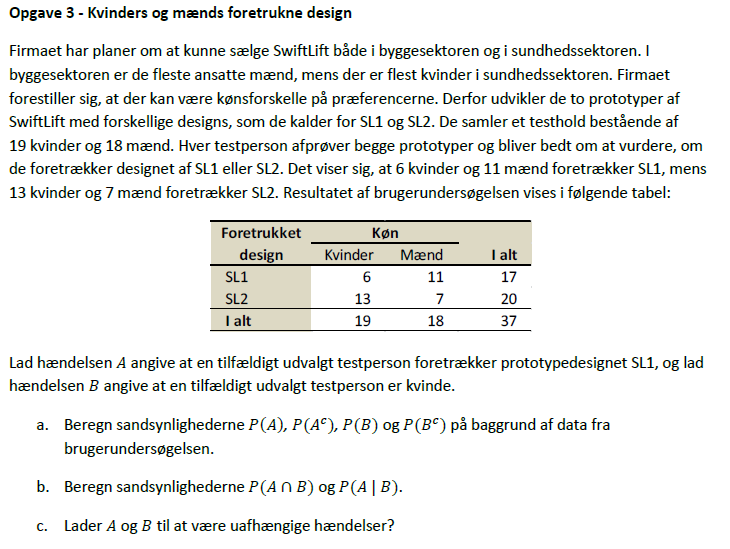

clc; clear;

% SL1 data
sl1_k = 6

sl1_k = 6

sl1_m = 11 

sl1_m = 11

sl1_tot = sl1_k + sl1_m

sl1_tot = 17


% SL2 data
sl2_k = 13

sl2_k = 13

sl2_m = 7 

sl2_m = 7

sl2_tot = sl2_k + sl2_m

sl2_tot = 20


% Populations antal
n_tot = sl1_tot + sl2_tot

n_tot = 37


%---------------------------------------------%
%---------------- Udregninger ----------------%
%---------------------------------------------%

% Opgave a)
pA = sl1_tot/n_tot

pA = 0.4595

pAc = 1-pA

pAc = 0.5405

pB = (sl1_k + sl2_k)/n_tot

pB = 0.5135

pBc = 1 - pB

pBc = 0.4865


% Opgave b)
pA_og_B = sl1_k/n_tot

pA_og_B = 0.1622

pA_hvis_B = sl1_k/sl1_tot

pA_hvis_B = 0.3529


% Opgave c)
pA == pA_hvis_B

ans = logical
   0


% Ved tjek om de 2 hændelser er ens, ses det at resultatet er 0, altså
% false, så de er afhængige

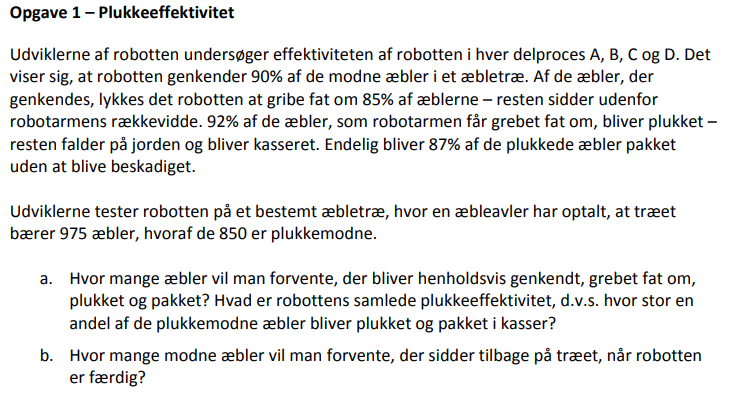

clc; clear;


pA = 0.9; pB = 0.85; pC = 0.92; pD = 0.87;

% Opgave a
n = 850; % Plukkemodne

n_genkendt = pA*n

n_genkendt = 765

n_grebet = pB * n_genkendt

n_grebet = 650.2500

n_plukket = pC * n_grebet

n_plukket = 598.2300

n_pakket = pD * n_plukket

n_pakket = 520.4601


% Opgave b
n_ikke_genkendt = (1 - pA) * n

n_ikke_genkendt = 85.0000

n_ikke_grebet = (1 - pB) * n_genkendt

n_ikke_grebet = 114.7500


n_modne_tilbage = n_ikke_genkendt + n_ikke_grebet

n_modne_tilbage = 199.7500

### Opgaver fra lektion 4

- Opgaver 1 - 3

clc; clear;




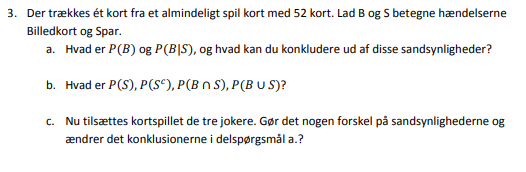

% Opgave 3
n = 52;
nbilled = 12;
nspar = 13;

%Opgave a
Pbilled = nbilled/n

Pbilled = 0.2308

Pspar = nspar/n

Pspar = 0.2500

P_billed_givet_spar = 3/n

P_billed_givet_spar = 0.0577

P_billed_givet_spar = Pbilled * Pspar

P_billed_givet_spar = 0.0577


P_billed_givet_spar = P_billed_givet_spar/Pspar

P_billed_givet_spar = 0.2308